# Resolución de Casos 02

- Sección: 5

- N° de grupo: 7

- Integrante 1 (líder): Mariela del Carmen Ocampo Lecca (100%)

- Integrante 2: Jasira Carelis Monzón Aiquipa (100%)

- Integrante 3: Christopher Daniel Moscoso Urbina (75%)

- Integrante 4: Javier Pariansullca Ventura (100%)

- Integrante 5: José Carlos Moscoso Saldamando (0%)

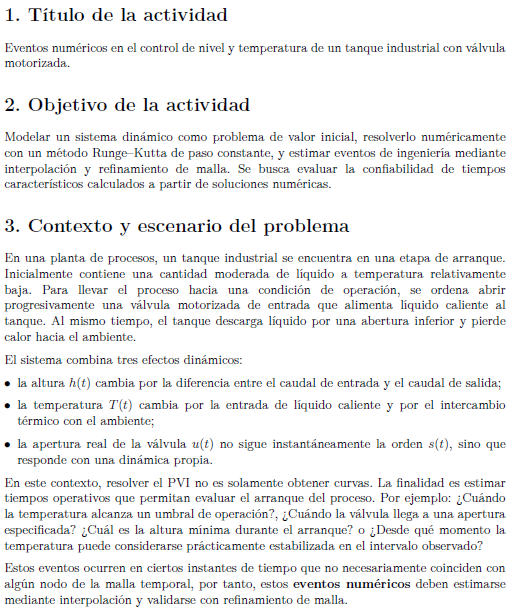

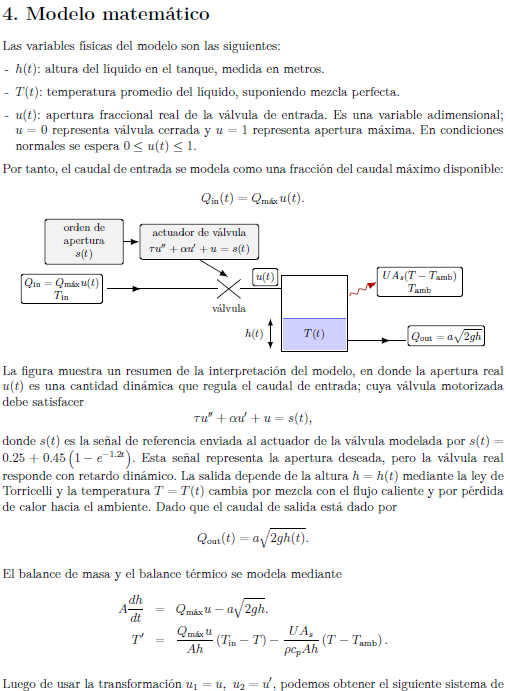

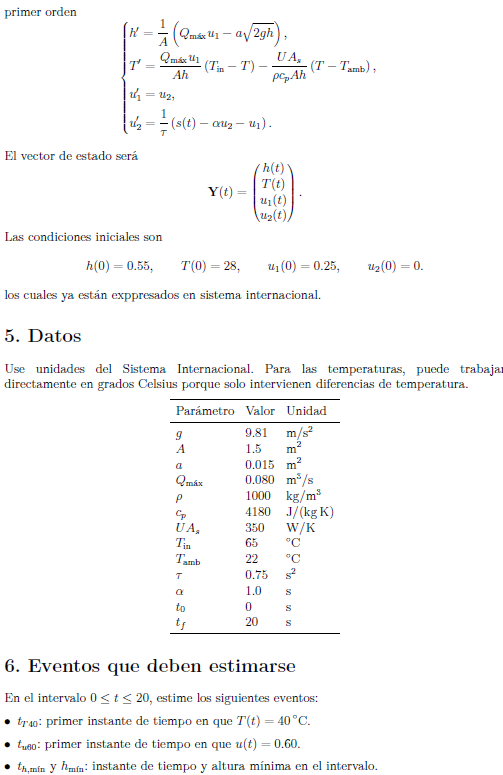

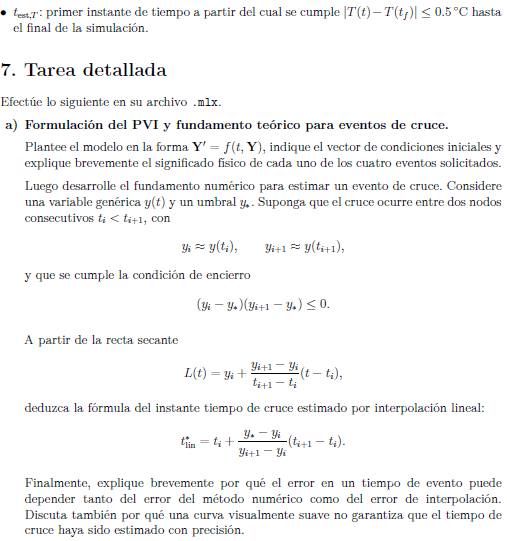

% Definimos los parámetros del sistema, el vector de condiciones iniciales y la señal de referencia de la válvula
g = 9.81;
A = 1.5;
a = 0.015;
Qmax = 0.080;
rho = 1000;
cp = 4180;
UAs = 350;
Tin = 65;
Tamb = 22;
tau = 0.75;
alpha = 1.0;
t0 = 0;
tf = 20;

Y0 = [0.55; 28; 0.25; 0];

s = @(t) 0.25 + 0.45 * (1 - exp(-1.2 * t));

% Definimos la función del PVI en la forma Y' = f(t, Y)
% Y(1) = h, Y(2) = T, Y(3) = u1, Y(4) = u2
f_pvi = @(t, Y) [ ...
    (1/A) * (Qmax * Y(3) - a * sqrt(2 * g * Y(1))); ...
    (Qmax * Y(3) / (A * Y(1))) * (Tin - Y(2)) - (UAs / (rho * cp * A * Y(1))) * (Y(2) - Tamb); ...
    Y(4); ...
    (1/tau) * (s(t) - alpha * Y(4) - Y(3)) ...
    ];


% Significado físico de cada uno de los 4 eventos
%
% Evento 1: Es el tiempo transcurrido hasta que el líquido alcanza los 40°C. 
% Mide la velocidad de calentamiento inicial.
%
% Evento 2: Es el tiempo en el que la apertura real de la válvula llega al 60%.
% Evalúa el retardo del actuador mecánico respecto a la orden s(t).
%
% Evento 3: Es el instante y el valor del nivel más bajo del tanque.
% Indica el punto crítico de vaciado transitorio antes de que el caudal de entrada supere al de salida.
%
% Evento 4: Es el tiempo en el que la temperatura se estabiliza dentro de una banda de tolerancia de +-0.5°C respecto al valor final.
% Indica que el proceso térmico entró en estado estacionario práctico.

**Fundamento numérico para estimar un evento de cruce**:

Queremos hallar el tiempo de cruce (t_lin*) donde la recta secante L(t) intercepta exactamente el umbral deseado (y_*). Es decir, L(t_lin*) = y_*

Partimos de la ecuación dada: y_* = y_i + ((y_{i+1} - y_i) / (t_{i+1} - t_i)) * (t_lin* - t_i)

Pasamos y_i restando al lado izquierdo: y_* - y_i = ((y_{i+1} - y_i) / (t_{i+1} - t_i)) * (t_lin* - t_i)

Multiplicamos ambos lados por el inverso de la pendiente: ((y_* - y_i) / (y_{i+1} - y_i)) * (t_{i+1} - t_i) = t_lin* - t_i

Despejamos t_lin* pasando t_i sumando al lado derecho: t_lin* = t_i + ((y_* - y_i) / (y_{i+1} - y_i)) * (t_{i+1} - t_i)

**¿Por qué el error en un tiempo de evento depende tanto del método numérico como del error de interpolación?**

Porque los puntos que usamos para interpolar ya vienen con error desde el método Runge-Kutta. Si a eso le sumamos que estamos aproximando una curva real uniendo los puntos con una línea recta, el resultado final arrastra ambos fallos de precisión.

**¿Por qué una curva visualmente suave no garantiza que el tiempo de cruce haya sido estimado con precisión?**

Porque la suavidad en la gráfica es solo un efecto visual que depende del zoom o de la pantalla. Si el paso de tiempo en la simulación es muy grande, la recta que tira la interpolación puede ignorar el verdadero comportamiento de la curva a nivel decimal. Por eso hay que verificar con refinamiento de malla.

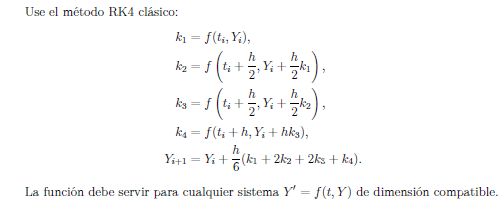

function [T, Y] = rk4_sistema(f, tspan, Y0, N)
t0 = tspan(1);
tf = tspan(2);
h = (tf - t0) / N;
T = (t0:h:tf)';
m = length(Y0);
Y = zeros(N + 1, m);
Y(1, :) = Y0';
for i = 1:N
    ti = T(i);
    Yi = Y(i, :)';
    k1 = f(ti, Yi);
    k2 = f(ti + h/2, Yi + (h/2)*k1);
    k3 = f(ti + h/2, Yi + (h/2)*k2);
    k4 = f(ti + h, Yi + h*k3);
    Y(i+1, :) = (Yi + (h/6)*(k1 + 2*k2 + 2*k3 + k4))';
end
end

N = 50 -> Tamaño de T: 51 filas, Tamaño de Y: 51 x 4
N = 100 -> Tamaño de T: 101 filas, Tamaño de Y: 101 x 4
N = 200 -> Tamaño de T: 201 filas, Tamaño de Y: 201 x 4
N = 400 -> Tamaño de T: 401 filas, Tamaño de Y: 401 x 4
N = 800 -> Tamaño de T: 801 filas, Tamaño de Y: 801 x 4


La funcion calcula el tamano de paso h dividiendo el tiempo total entre N y arma el vector de tiempos T. Luego crea una matriz vacia de ceros donde cada fila guarda un instante de tiempo y cada columna una variable diferente, metiendo los valores iniciales en la primera fila. Despues corre un bucle desde 1 hasta N donde en cada paso saca los datos de la fila actual, calcula las cuatro pendientes k1, k2, k3 y k4 con las formulas de la guia, saca el promedio ponderado de estas para calcular el siguiente estado y lo guarda en la siguiente fila de la matriz. Al terminar el bucle te devuelve el vector de tiempos y la matriz con toda la simulacion lista.

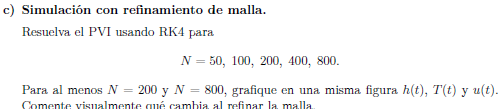

Ns = [50, 100, 200, 400, 800];

Estado inicial (t=0): h=0.550, T=28.0, u1=0.250



% contenedore que guaran las soluciones
%vectores de tiempo 
sol_T = cell(length(Ns), 1); 

Estado final (t=20) con N=800: h=0.593 m, T=54.52 °C, u1=0.7000


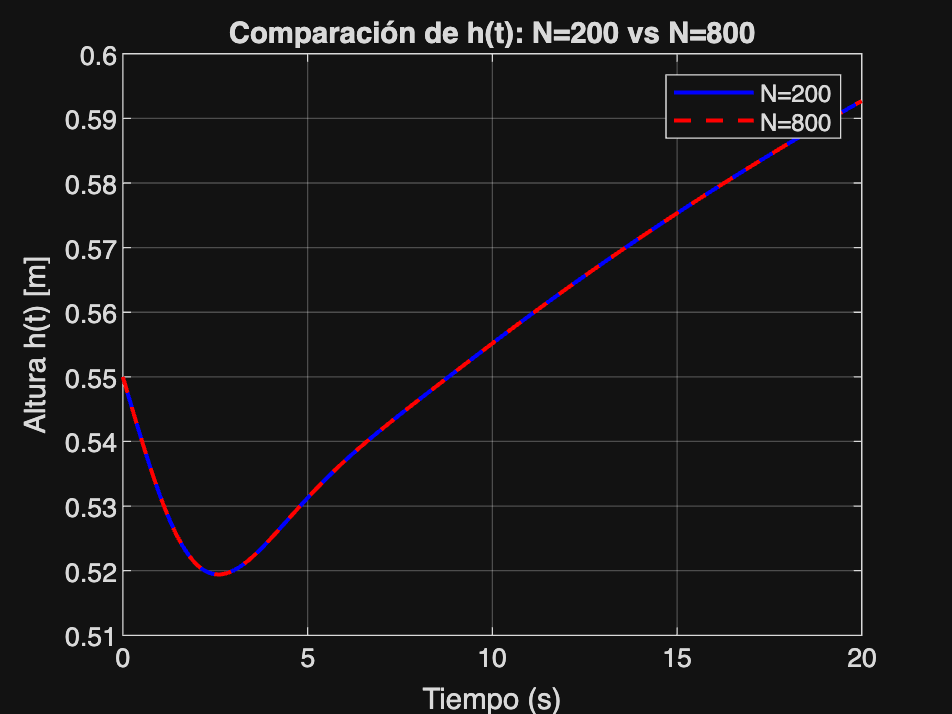

% matrices de estado
sol_Y = cell(length(Ns), 1); 

% bucle principal
for i = 1:length(Ns)
    N = Ns(i);
    [T, Y] = rk4_sistema(f_pvi, [t0, tf], Y0, N);
    sol_T{i} = T;
    sol_Y{i} = Y;
end

for i = 1:length(Ns)

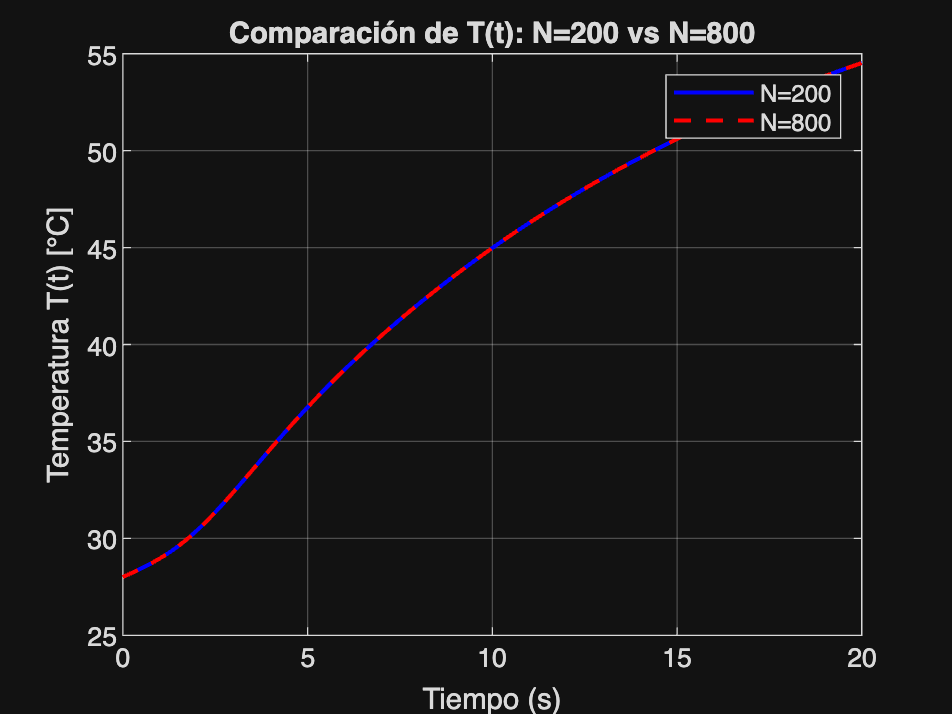

    fprintf('N = %d -> Tamaño de T: %d filas, Tamaño de Y: %d x %d\n', ...
            Ns(i), length(sol_T{i}), size(sol_Y{i}, 1), size(sol_Y{i}, 2));
end

% Estado inicial 
fprintf('Estado inicial (t=0): h=%.3f, T=%.1f, u1=%.3f\n', Y0(1), Y0(2), Y0(3));

% Estado final para la malla más fina (N=800)

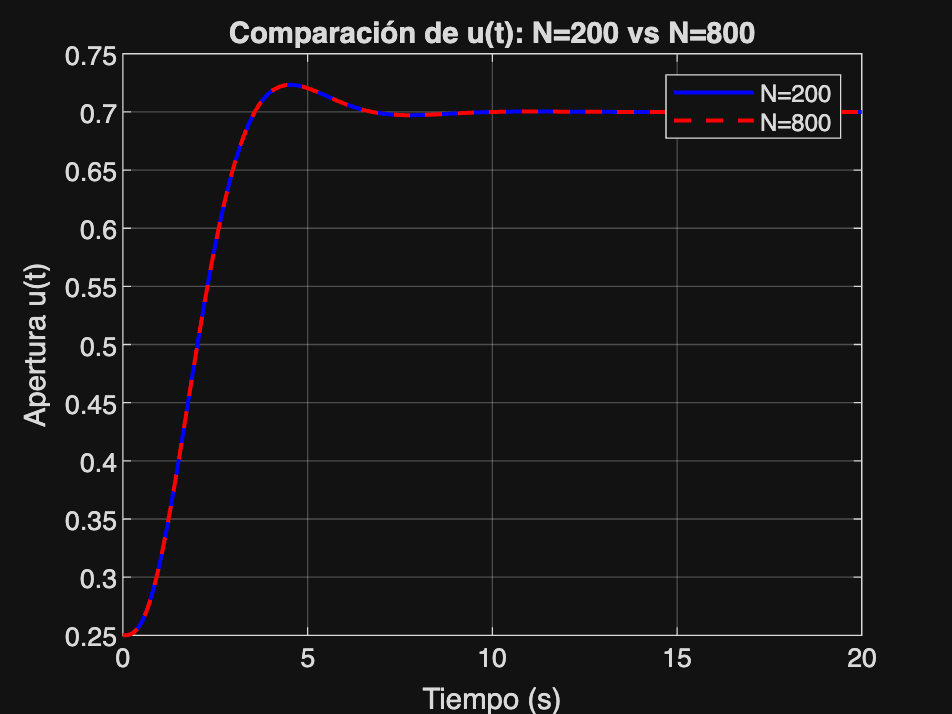

Y_final_800 = sol_Y{5}(end, :); fprintf('Estado final (t=20) con N=800: h=%.3f m, T=%.2f °C, u1=%.4f\n', ...
        Y_final_800(1), Y_final_800(2), Y_final_800(3));

% Extraemos los datos de N=200 y N=800 para comparar
T_200 = sol_T{3}; Y_200 = sol_Y{3};
T_800 = sol_T{5}; Y_800 = sol_Y{5};

% Grafica 1: Altura h(t)

figure;
plot(T_200, Y_200(:,1), 'b-', 'LineWidth', 1.5); hold on;
plot(T_800, Y_800(:,1), 'r--', 'LineWidth', 1.5);
xlabel('Tiempo (s)'); ylabel('Altura h(t) [m]');
title('Comparación de h(t): N=200 vs N=800');
legend('N=200', 'N=800'); grid on;

% Gráfica 2: Temperatura T(t) 
figure;
plot(T_200, Y_200(:,2), 'b-', 'LineWidth', 1.5); hold on;
plot(T_800, Y_800(:,2), 'r--', 'LineWidth', 1.5);
xlabel('Tiempo (s)'); ylabel('Temperatura T(t) [°C]');
title('Comparación de T(t): N=200 vs N=800');
legend('N=200', 'N=800'); grid on;

% Gráfica 3: Apertura de válvula u(t) 
figure;
plot(T_200, Y_200(:,3), 'b-', 'LineWidth', 1.5); hold on;
plot(T_800, Y_800(:,3), 'r--', 'LineWidth', 1.5);
xlabel('Tiempo (s)'); ylabel('Apertura u(t)');
title('Comparación de u(t): N=200 vs N=800');
legend('N=200', 'N=800'); grid on;

Las tres variables de estado muestran comportamientos físicamente consistentes con el modelo: 

h(t) presenta una caída inicial seguida de recuperación, producto del desbalance momentáneo entre los  Qin y Qout mientras la válvula aún no alcanza suficiente apertura. 

 T(t) crece de forma sigmoide hacia su valor de equilibrio térmico iniciano desde 28°C hasta acercarse a 55°C, tiene un crecimiento rapido en un incio, a medida que T(t) se acerca a su valor de equilibrio, el crecimiento va disminuyendo levemente. 

u(t) exhibe un sobrepico característico de un actuador de segundo orden subamortiguado antes de asentarse cerca de 0.70.

 Al comparar N=200 con N=800, las curvas se superponen casi perfectamente en las tres subgráficas, incluso en la zona del mínimo de h(t), lo que nos indica que N=200 ya es suficiente para representar visualmente la dinámica del sistema. Sin embargo, esta coincidencia visual no garantiza que los eventos numéricos (instantes exactos de cruce o el valor del mínimo) coincidan con la misma precisión, ya que diferencias del orden de h^4 solo se hacen evidentes al comparar varias cifras decimales.

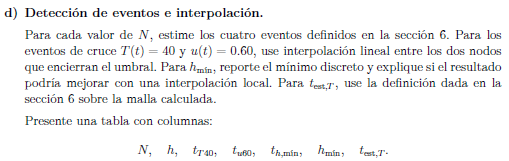

% creamos los espacions en los que se guardaran lios eventos cada uno en
% una posicion 
tT40_v  = zeros(length(Ns),1);
tu60_v  = zeros(length(Ns),1);
thmin_v = zeros(length(Ns),1);
hmin_v  = zeros(length(Ns),1);

     N      tT40      tu60     th_min     h_min     test_T
    ___    ______    ______    ______    _______    ______

     50    6.7291    2.6075      2.4     0.51956      19.6
    100    6.7285    2.5955      2.6     0.51942      19.4
    200    6.7282    2.5954      2.6     0.51942      19.3
    400    6.7281    2.5953      2.6     0.51942      19.3
    800    6.7281    2.5953    2.575     0.51942    19.275



test_v  = zeros(length(Ns),1);

% recorremos las 5 siulacion que tenmos en el itme c
for i = 1:length(Ns)
    T = sol_T{i};
    Y = sol_Y{i};

    %usamos la funcion 
    [t_T40, t_u60, t_hmin, h_min, t_est_T] = detectar_eventos(T, Y);

    %los resultados lo guardamos en cada posicion de los espasioc
    tT40_v(i)  = t_T40;
    tu60_v(i)  = t_u60;
    thmin_v(i) = t_hmin;
    hmin_v(i)  = h_min;
    test_v(i)  = t_est_T;
end

%tabla de rsultados
N_col = Ns(:);
Tabla_eventos = table(N_col, tT40_v, tu60_v, thmin_v, hmin_v, test_v, ...
    'VariableNames', {'N','tT40','tu60','th_min','h_min','test_T'});
disp(Tabla_eventos)


% funcion para detectar los 4 eventos 
function [t_T40, t_u60, t_hmin, h_min, t_est_T] = detectar_eventos(T, Y)
    % E1. t_T40 (Temperatura cruza 40°C) 
    t_T40 = NaN;
    for i = 1:length(T)-1
        if (Y(i,2) - 40) * (Y(i+1,2) - 40) <= 0
            t_T40 = T(i) + (40 - Y(i,2)) / (Y(i+1,2) - Y(i,2)) * (T(i+1) - T(i));
            break;
        end
    end

    % E2: t_u60 (Apertura cruza 0.60) 
    t_u60 = NaN;
    for i = 1:length(T)-1
        if (Y(i,3) - 0.60) * (Y(i+1,3) - 0.60) <= 0
            t_u60 = T(i) + (0.60 - Y(i,3)) / (Y(i+1,3) - Y(i,3)) * (T(i+1) - T(i));
            break;
        end
    end

    % E3: h_min altura mínima discreta 
    [h_min, idx] = min(Y(:,1));
    t_hmin = T(idx);

    % E4: t_est_T, estabilizacion de la temperatura
    T_final = Y(end, 2);
    indices_fuera = find(abs(T_final - Y(:,2)) > 0.5);
    if isempty(indices_fuera)
        t_est_T = T(1);
    else
        t_est_T = T(indices_fuera(end) + 1);
    end
end

El evento tT40 es el momento en que el líquido del tanque llega por primera vez a 40°C, y nos dice qué tan rápido se está calentando el proceso al inicio. Para hallarlo, se revisó la temperatura en cada par de instantes consecutivos hasta encontrar dónde pasa de estar por debajo de 40°C a estar por encima (o al revés), y entre esos dos puntos se calculó el tiempo exacto de cruce usando la fórmula de interpolación lineal.

 El evento tu60 es el momento en que la válvula llega realmente al 60% de apertura, y muestra qué tanto se demora el mecanismo de la válvula en responder a la orden que se le da. Se calculó de la misma forma que el evento anterior, pero revisando la apertura en vez de la temperatura: se buscó entre qué dos instantes la apertura pasa por 0.60, y se interpoló para obtener el tiempo exacto.

El evento th,mín y hmín es el momento y el nivel más bajo que alcanza el líquido en el tanque durante el arranque, justo antes de que empiece a llenarse más de lo que se vacía. Aquí no se interpoló nada: simplemente se buscó el valor más pequeño dentro de todos los datos de altura ya calculados, y se tomó el tiempo correspondiente a ese punto directamente de la simulación.

El evento test,T es el momento a partir del cual la temperatura ya no se aleja más de 0.5°C de su valor final, es decir, cuando el sistema prácticamente deja de cambiar de temperatura. Para calcularlo, se tomó la temperatura final como referencia, se identificaron todos los instantes en que la temperatura todavía estaba más lejos de 0.5°C de ese valor, y se tomó el instante justo después del último de esos casos como el momento de estabilización.

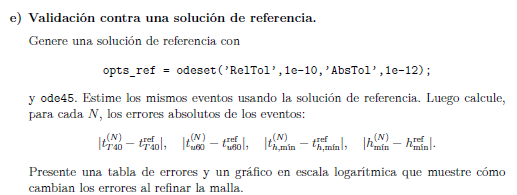

% Definimos las opciones de alta precisión para ode45
opts_ref = odeset('RelTol', 1e-10, 'AbsTol', 1e-12);
[T_ref, Y_ref] = ode45(f_pvi, [t0, tf], Y0, opts_ref);
[tT40_ref, tu60_ref, thmin_ref, hmin_ref, test_ref] = detectar_eventos(T_ref, Y_ref);

--- TABLA DE ERRORES ABSOLUTOS ---


     N      Err_tT40      Err_tu60     Err_th_min    Err_h_min 
    ___    __________    __________    __________    __________

     50     0.0010235       0.01226      0.18438     0.00014071
    100    0.00040195    0.00024611     0.015616     5.7474e-07
    200    8.7755e-05    0.00013309     0.015616     7.9945e-07
    400    2.6719e-05    6.4907e-05     0.015616     8.1296e-07
    800    2.7855e-06    2.9063e-05    0.0093842     4.5565e-07



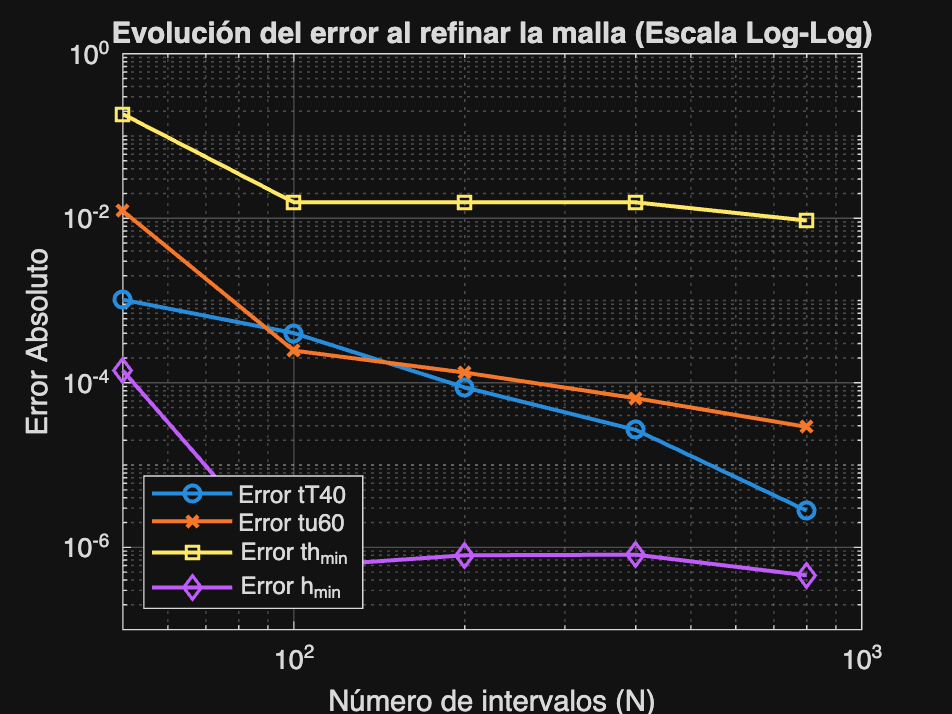

% Inicializamos los vectores para guardar los errores absolutos de cada N
err_tT40  = zeros(length(Ns), 1);
err_tu60  = zeros(length(Ns), 1);
err_thmin = zeros(length(Ns), 1);
err_hmin  = zeros(length(Ns), 1);

% Sacamos la diferencia absoluta entre lo que dio RK4 y la referencia de ode45
for i = 1:length(Ns)
    err_tT40(i)  = abs(tT40_v(i) - tT40_ref);
    err_tu60(i)  = abs(tu60_v(i) - tu60_ref);
    err_thmin(i) = abs(thmin_v(i) - thmin_ref);
    err_hmin(i)  = abs(hmin_v(i) - hmin_ref);

end

% Armamos la tabla de errores absolutos para mostrarla en pantalla
Tabla_errores = table(N_col, err_tT40, err_tu60, err_thmin, err_hmin, ...
    'VariableNames', {'N', 'Err_tT40', 'Err_tu60', 'Err_th_min', 'Err_h_min'});
disp('TABLA DE ERRORES ABSOLUTOS');
disp(Tabla_errores);

% Graficamos los errores en escala logarítmica para ver cómo caen al refinar
figure;
loglog(Ns, err_tT40, '-o', 'LineWidth', 1.5); hold on;
loglog(Ns, err_tu60, '-x', 'LineWidth', 1.5);
loglog(Ns, err_thmin, '-s', 'LineWidth', 1.5);
loglog(Ns, err_hmin, '-d', 'LineWidth', 1.5);
xlabel('Número de intervalos (N)');
ylabel('Error Absoluto');
title('Evolución del error al refinar la malla (Escala Log-Log)');
legend('Error tT40', 'Error tu60', 'Error th_{min}', 'Error h_{min}', 'Location', 'southwest');
grid on;

      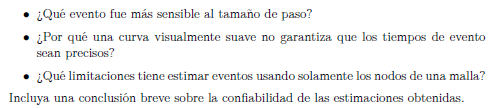

1) El menor valor aceptable seria N = 400. Al mirar la tabla de errores comparada con ode45, recien en ese punto los errores de tiempo bajan notablemente y se quedan en milisegundos o centesimas de segundo. Con N = 50 o 100 los desfases de tiempo son muy grandes como para confiar en ellos.

2) El evento mas sensible de todos fue el tiempo de la altura minima (th_min). En el grafico se nota porque su error no disminuye de forma tan constante o lineal como los eventos de cruce de temperatura o de valvula. Esto pasa porque no usamos interpolacion para este evento, sino que dependemos exclusivamente de tener la suerte de que el nodo de la malla caiga justo en el punto mas bajo del grafico.

3) Porque la suavidad en un grafico es un engaño visual que depende del zoom que le hagas o de como la pantalla une los puntos con lineas rectas. Una curva simulada con N = 50 puede verse perfecta y sin quiebres a simple vista, pero cuando buscas el cruce exacto en los decimales, el tiempo real puede estar desfasado por decimas de segundo, lo cual es un error tremendo.

4) La limitacion principal es que estamos amarrados a los tiempos fijos que calcula el metodo. Si el valor real del minimo o del cruce de temperatura ocurre a mitad de camino entre dos nodos, el programa no lo va a ver y se vera obligado a tomar el nodo mas cercano. Eso causa un error de redondeo gigante a menos que se usen formulas de interpolacion o una malla exageradamente fina.

En conclusion, las estimaciones calculadas combinando el metodo RK4 con la formula de interpolacion lineal son muy confiables y precisas a partir de N = 400. El unico punto debil es el calculo del minimo (th_min), ya que al depender solo de los nodos discretos, pierde precision y demuestra que para optimizar extremos se necesitarian mallas mas finas o usar una interpolacion parabolica para asegurar el resultado.